# `CIE_442 (DSP)`

# `SDR Project`

# `(Software Defined Radio)`

`Ahmed Mohamed Elsehmawy    202001919`

`Omar Elsayed               202100597`

`Nada Ghafagy               202001944`

`Nihal Ahmed                202100471`

## Filter Design:

- **Problem Statement:**

                    In the context of signal processing for a communication system involving the transmission of 6 uplinked signals, the challenge lies in designing an effective filter that balances the trade-offs between various filter characteristics. Unlike the ideal filter with an impractical infinitely long impulse response, our goal is to find a compromise that optimizes the filter design.

                    The primary concern in this design is the reconstruction of each of the 6 uplinked signals, with a limited frequency span of "20 kHz" between the end of one signal and the start of the next. Ensuring a relatively small "transition region" becomes crucial for seamless signal reconstruction. Additionally, the reconstruction process aims to decode information bits encoded at the transmitter side, making it essential to minimize pass band ripples.

                    However, the challenge intensifies as we strive to maintain a balance between reducing pass band attenuation and increasing stop band attenuation while keeping the filter order (number of filter coefficients) relatively small. The objective is to strike a delicate balance that minimizes computational complexity and avoids an excessive increase in the order of the filter, which could lead to an impractical and resource-intensive solution. Thus, the design must navigate these conflicting requirements to achieve an optimal compromise for effective signal reconstruction with 6 uplinked signals

### **Design Constraints:**

- **The stop band attenuation:**

                When assessing the magnitude difference of one of the generated signals, it was observed that the discrepancy between the signal magnitude at "90 kHz" (the conclusion of the signal's frequency range) and the signal magnitude at "110 kHz" (intended to be the starting frequency of the next signal) is approximately -21 dB. Consequently, the stop band attenuation requirement is to exceed or equal 21 dB in the negative range.

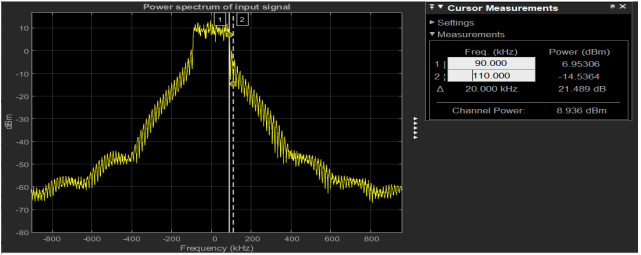

- **The transition region:**

                Upon visualizing the transmitted signal, which results from the frequency multiplexing of the six uplink generated signals, it has been determined that, in accordance with the stand-alone standard, the bandwidth for each signal is "180 kHz." The span is "200 kHz," representing the separation between the center frequencies of any two consecutive signals, and there remains only a "20 kHz" guard band between the two signals. As a result, the transition region in our design needs to be within the range of 20 kHz to a maximum of 30 kHz. This ensures that, at a distance of 20 kHz from the signal, the attenuation value remains sufficiently small to avoid signal distortion.

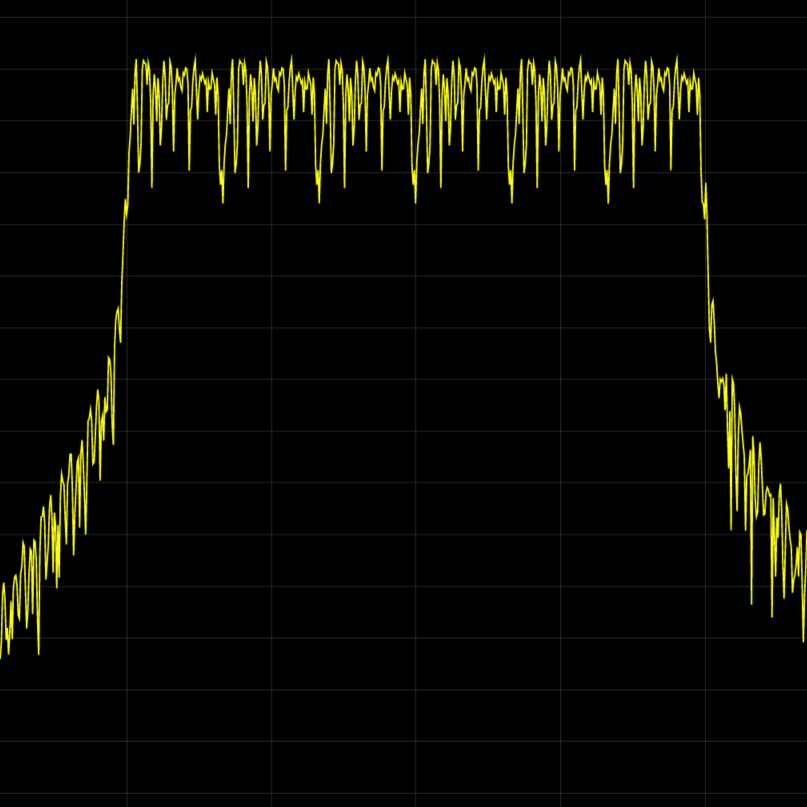

- **Filter Complexity: (Filter order)**

                  The complexity of the filter is quantified by a dimensionless number, which corresponds to the count of filter coefficients or taps. This count directly influences the number of multiplications involved in the filter application. Consequently, a higher number of filters corresponds to increased filter complexity and computational load. Therefore, it is more favorable to minimize the filter order. Considering the digital filtering challenge at hand, achieving a filter order of no more than 200 would be highly satisfactory.

- **Pass band Ripples:**

                   The pass band ripples indicate the deviation or distortion of the filter within the pass band and the expected attenuation within the signal's pass band. In the context of our digital filtering challenge, ensuring minimal distortion of our pass frequencies is crucial for reconstructing the input binary bits generated at the transmitter. Therefore, it is highly desirable to have a low value for the pass band ripples. Ideally, the pass band ripples value should fall within the range of 0.2 dB to 0.3 dB.

### **Design process:**

- **The filter prototypes:**

                       We've selected five distinct designs to iteratively assess and compare each prototype against our established constraints and requirements for the optimal filter design. The table below outlines the input parameters for each design method, enabling a comprehensive evaluation.

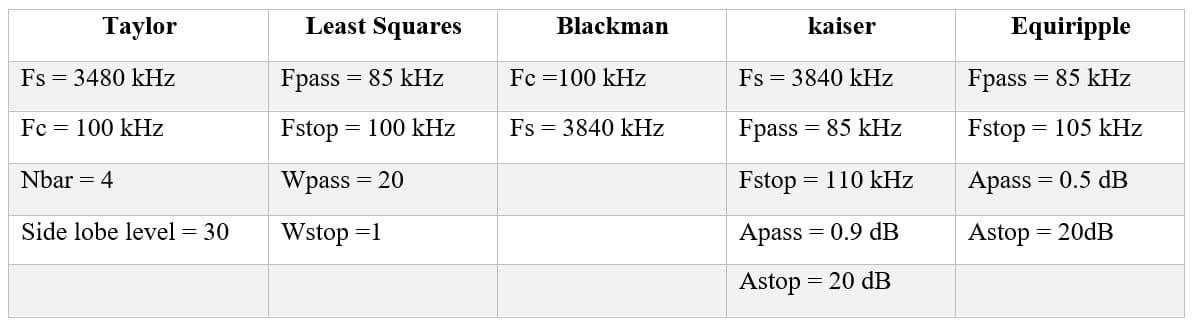

### **Qualitative analysis of the prototypes:**

**1-Taylor: (Window filter)**

            Despite the effectiveness of this window type and the specified input parameters in ensuring minimal pass band ripples and significant negative stop band attenuation, the design's critical drawback lies in its wide transition region bandwidth. This misleading factor is anticipated to lead to the exclusion of this design from the list of nominees.

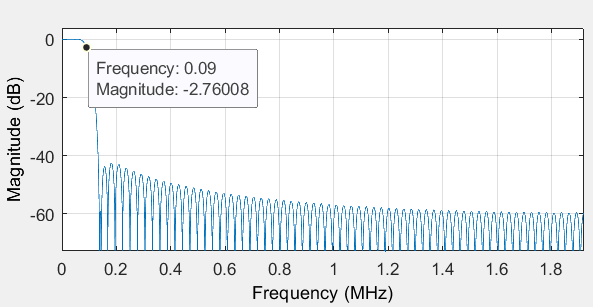

**2-Least Squares: **

            This filter prototype demonstrated satisfactory performance at lower orders by keeping pass band ripples within an acceptable range. However, the stop band attenuation was notably distortive and could significantly impact our signal. Moreover, when examining the filter's frequency response on a linear scale, it became evident that its transition region bandwidth is unsuitable for our filtering needs. Nonetheless, despite these drawbacks, this filter remains a preferred candidate.

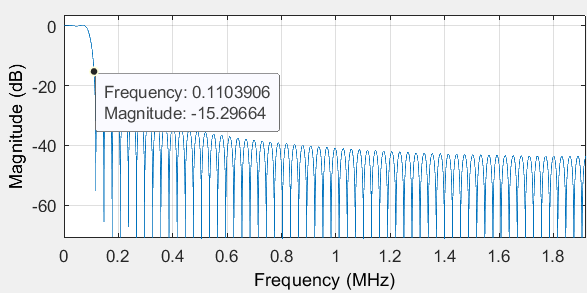

**3-Blackman: (Window filter)**

            While the Blackman window filter achieved highly satisfactory values for pass band ripples and stop band attenuation, it fell short in maintaining an acceptable transition region bandwidth. Additionally, the complexity of the filter was relatively high.

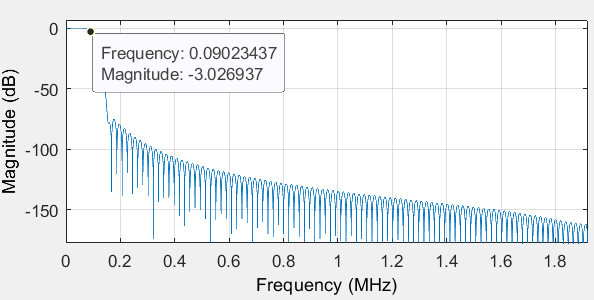

**4-Kaiser: (Window filter)**

            Upon visualizing its response, this filter has demonstrated the most favorable trade-off observed thus far. Notably, the filter exhibited no divergent parameters. The acceptable compromise across pass band ripples, stop band attenuation, and transition region bandwidth, coupled with a reasonable order, positions this filter as a strong candidate.

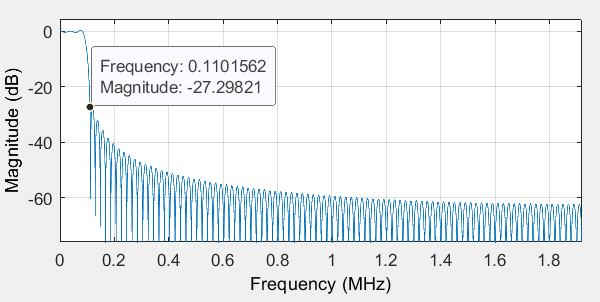

**5-Equiripple:**

            The equiripple filter has achieved a commendable compromise among filter constraints, featuring satisfactory stop band attenuation and transition region bandwidth, coupled with relatively low pass band ripples. This filter deserves careful consideration in our evaluation.

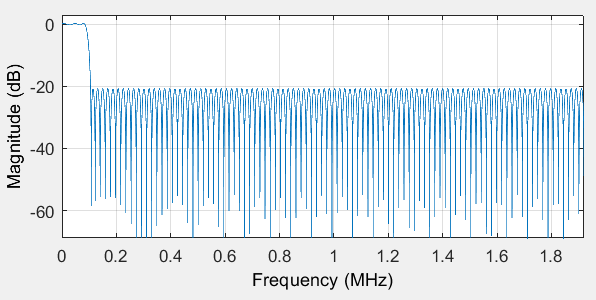

### **Quantitative Analysis:**

The next step includes calculating the values of the filter parameters represented in: Filter order, Pass band ripples, Stop band attenuation, and transition region bandwidth. The following table illustrates the output values of each of the five prototypes.

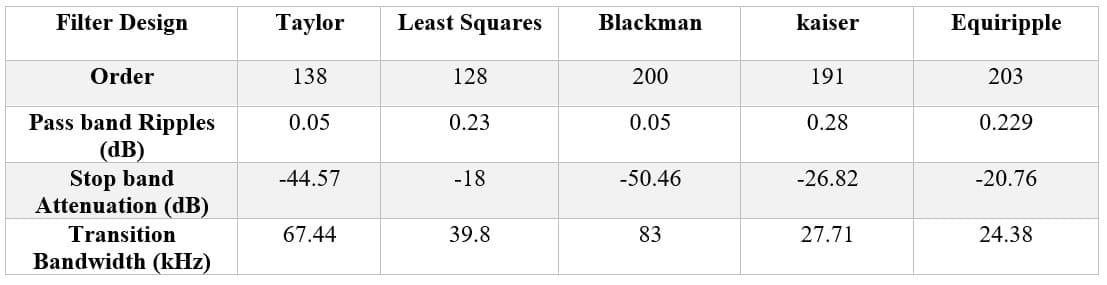

### **The evaluation criteria:**

            The selection process will be guided by the constraints and requirements we've specified. Each prototype will be assessed for compatibility, with a scoring system assigning up to 2 points for each of the 4 constraints, totaling 8 points. Scores will range from "-1" to "2" based on the degree of adherence to our design constraints. The prototype with the highest compatibility score will be employed in both the transmission and reception processes. The table below outlines the scoring range for each filter parameter.

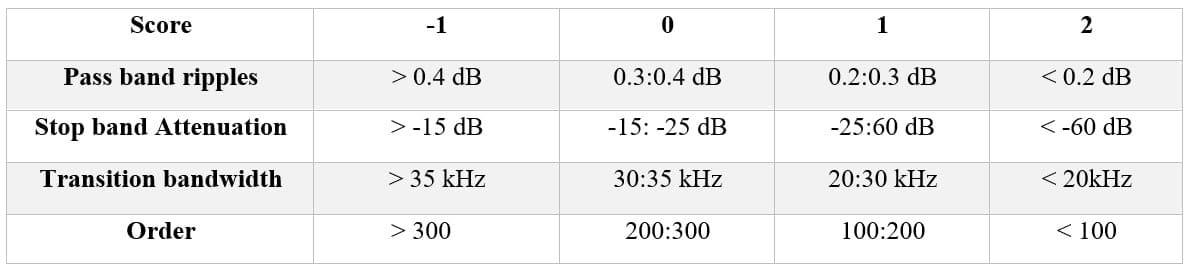

### **Implementation of the evaluation criteria:**

To evaluate each design, we will use an iterative code that assigns a specific score to each prototype based on the specified criteria. An array will be constructed to store the specifications of the five proposed prototypes, including pass band ripples (dB), stop band attenuation (dB), transition region bandwidth (kHz), and filter order. The filter design process will involve iterating over the specifications of the five designs, scoring each design based on quantitative evaluation criteria. The prototype with the highest score will be selected for implementation in both the transmission and receiving stages of our digital filtering problem.

  % Concatenate each filter's specifications together in a single array
   Equiripple_specs= [0.229,-20.76,24.38,203];
   Taylor_specs= [0.05,-44.57,67.44,138];
   Leastsq_specs= [0.23,-18,39.8,128];
   Kaiser_specs= [0.28,-26.82,27.71,191];
   Blackman_specs= [0.05,-50.46,83,200];
   Specs= [Equiripple_specs Taylor_specs Leastsq_specs Kaiser_specs Blackman_specs]

Specs =     0.2290  -20.7600   24.3800  203.0000    0.0500  -44.5700   67.4400  138.0000    0.2300  -18.0000   39.8000  128.0000    0.2800  -26.8200   27.7100  191.0000    0.0500  -50.4600   83.0000  200.0000


Iterating on every filter's specifications in order to chose the filter with highest score according to the evaluation criteria

scores=zeros(1,5);
j=1;  
k=1;
for i=1:length(Specs) 
        
       if mod((i-1),4)==0 && i>1
           j=j+1;
       end

% Scoring the filter's passband ripples value according to the evaluation criteria 
    if k==1
        if Specs(i)>0.4
        scores(j)=scores(j)-1;

        elseif Specs(i)>0.3 && Specs(i)<0.4
        scores(j)=scores(j);

        elseif Specs(i)>0.2 && Specs(i)<0.3
          scores(j)=scores(j)+1;

        else
        scores(j)=scores(j)+2;
        end

% Scoring the filter's stopband attenuation value for each filter design 

  elseif k==2

        if Specs(i)>-15
        scores(j)=scores(j)-1;

        elseif Specs(i)>-25 && Specs(i)<-15
        scores(j)=scores(j);

        elseif Specs(i)>-60 && Specs(i)<-25
          scores(j)=scores(j)+1;  

        else
        scores(j)=scores(j)+2;
        end

% Scoring the filter's transition region bandwidth value for each filter design 
    elseif k==3

        if Specs(i)>35
        scores(j)=scores(j)-1;

        elseif Specs(i)>30 && Specs(i)<35
        scores(j)=scores(j);

        elseif Specs(i)>20 && Specs(i)<30
          scores(j)=scores(j)+1;  

        else
        scores(j)=scores(j)+2;
        end

% Scoring the filter's order (number of coefficients) for each filter design 
    else
        if Specs(i)>300
        scores(j)=scores(j)-1;

        elseif Specs(i)>201 && Specs(i)<300
        scores(j)=scores(j);

        elseif Specs(i)>100 && Specs(i)<201
          scores(j)=scores(j)+1;  

        else
        scores(j)=scores(j)+2;
        end
    end
   if k==4
    k=0;
   end
   k=k+1;
   end


Importing the coefficients of the filter design that got the best score and displaying the optimal filter window type, alongside with its coefficients and frequency response. 

   %getting the index of the filter having the highest score
   [Mx,I] = max(scores);

   %Importing the filter coefficients of the optimal filter
   if I==1
      Filter_optimal= cell2mat(struct2cell(load('Equiripple.mat')));
      disp("Optimal Filter has been found to be Equiripple");

   elseif I==2
      Filter_optimal= cell2mat(struct2cell(load('Taylor.mat')));
      disp("Optimal Filter has been found to be Taylor");

   elseif I==3

      Filter_optimal= cell2mat(struct2cell(load('leastsq.mat')));
      disp("Optimal Filter has been found to be Least squares");

   elseif I==4
      Filter_optimal= cell2mat(struct2cell(load('Kaiser.mat')));
      disp("Optimal Filter has been found to be Kaiser");

   else 
      Filter_optimal= cell2mat(struct2cell(load('Blackman.mat')));
      disp("Optimal Filter has been found to be Blackman");
   end

Optimal Filter has been found to be Kaiser


### The evaluation process output:

 Following the execution of the evaluation process, the Kaiser Window Filter emerged as the top-performing filter, achieving the highest score. This filter was employed for both the transmission and reception of the NB-IoT signal. As anticipated, it demonstrated exceptional performance on the signal and proved highly effective in handling our digital filtering requirements.

   
   %Visulaizing the filter coefficients and the frequency response of the
   %filter
   disp(Filter_optimal);

    0.0009    0.0012    0.0015    0.0018    0.0020    0.0022    0.0023    0.0024    0.0024    0.0023    0.0022    0.0020    0.0018    0.0015    0.0012    0.0008    0.0003   -0.0001   -0.0006   -0.0011   -0.0015   -0.0020   -0.0024   -0.0028   -0.0031   -0.0033   -0.0035   -0.0036   -0.0036   -0.0035   -0.0033   -0.0030   -0.0026   -0.0021   -0.0016   -0.0010   -0.0003    0.0004    0.0011    0.0019    0.0026    0.0033    0.0039    0.0045    0.0050    0.0053    0.0056    0.0057    0.0057    0.0055    0.0051    0.0046    0.0040    0.0032    0.0023    0.0013    0.0001   -0.0011   -0.0023   -0.0036   -0.0048   -0.0060   -0.0071   -0.0081   -0.0090   -0.0097   -0.0101   -0.0104   -0.0104   -0.0101   -0.0095   -0.0086   -0.0074   -0.0059   -0.0040   -0.0019    0.0005    0.0031    0.0060    0.0091    0.0123    0.0157    0.0191    0.0225    0.0260    0.0293    0.0326    0.0357    0.0385    0.0412    0.0435    0.0455    0.0471    0.0484    0.0492    0.0496    0.0496    0.0492    0.0484    0.0471

   disp("The filter's frequency response");

The filter's frequency response


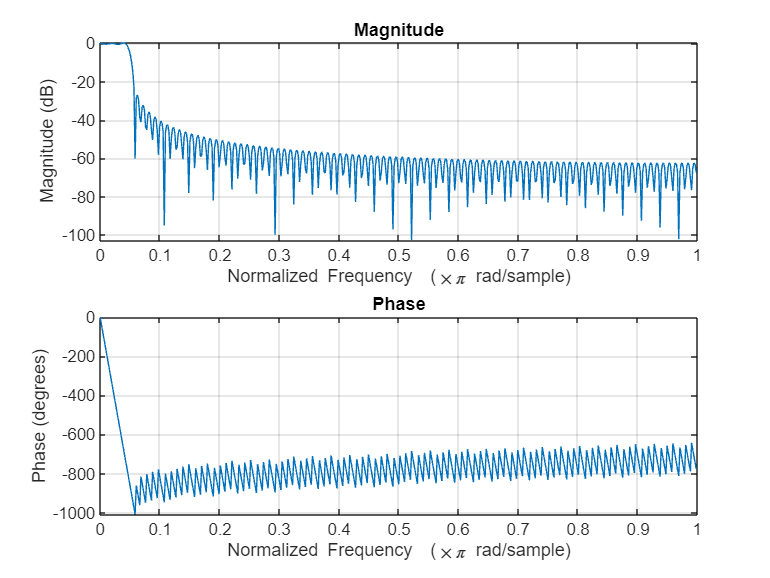

   freqz(Filter_optimal,1);

## **The Transmitter Side: (UL NB-IoT devices)  **

% IF declaration and the subspacing among the carriers
Subspacing= '15kHz';
IF_1=1e05;
Trans_Signal=zeros(307200,1);
for i=1:6
%generating each of the 6 uplink complex baseband waveforms
     [wave,Fs]=Generate_NBiot();
     if i==1
     [signal,f] = pwelch(wave,2048,1024,2048,Fs);
     signal = signal/max(abs(signal));
     figure;plot(f/1e3,20*log10(signal))
     xlabel('Frequency in (KHz)')
     ylabel('Normalized Magnitude (dB)')
     end
if i==3
generated = dsp.SpectrumAnalyzer('SampleRate',Fs,'Title',' The uplink generated waveform signal');
  generated(wave);
end

Upsampling each of the 6 signals and applying a low pass FIR filter to capture the frequency span of the signal. Then passing it through a low-pass filter

%Upsampling the signal by a factor of 2
    Upsampling_Wave=upsample(wave,2);
%filtering the signal using a Low Pass Filter
    wave_filtered=filter(Filter_optimal,1,Upsampling_Wave);

Digital Up conversion of every signal to its intermediate frequency. The output of this stage is the composite IF signal that will be received at the base station. 

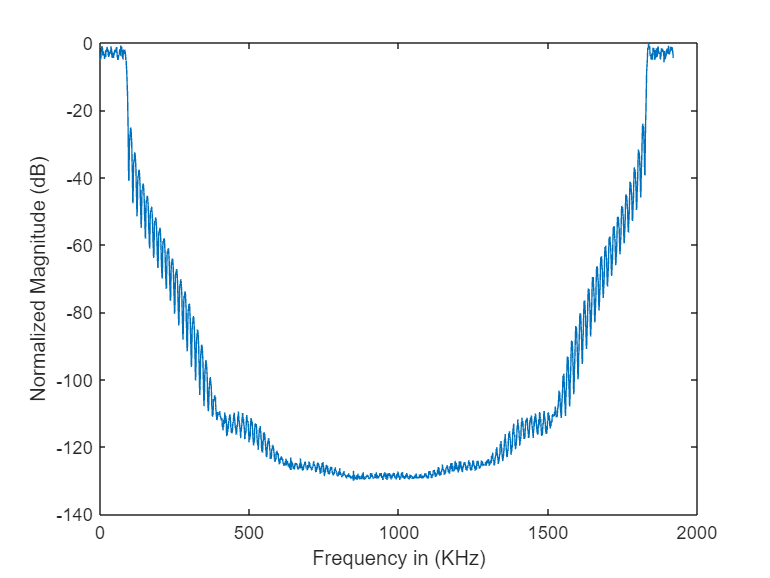

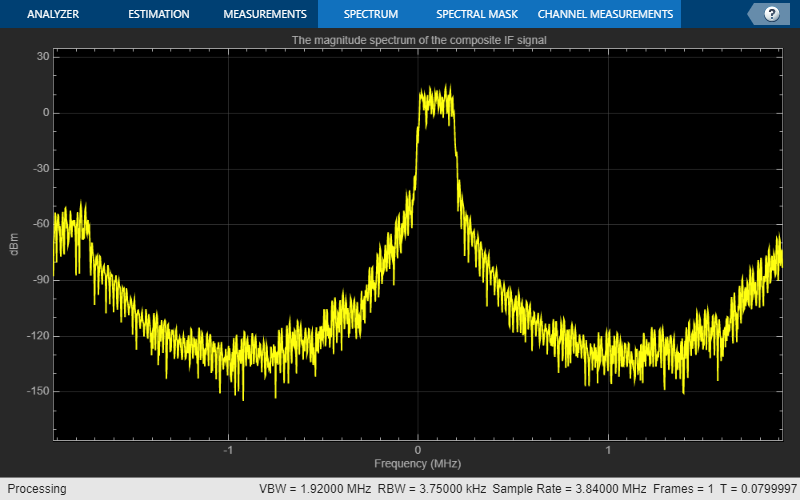

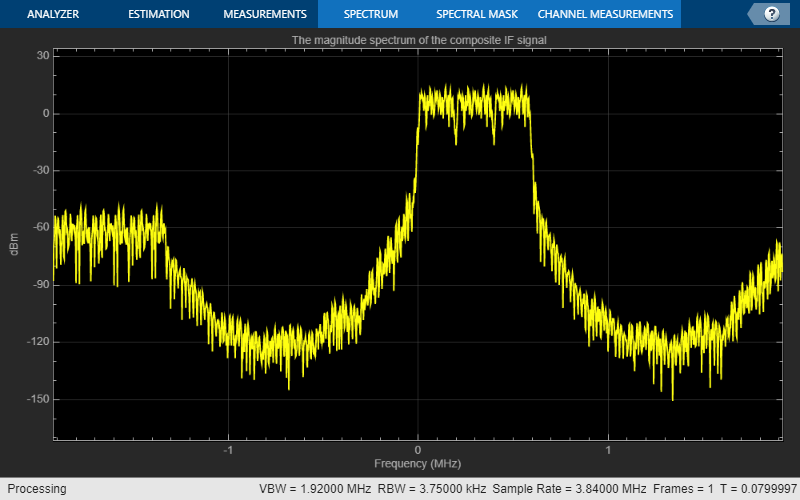

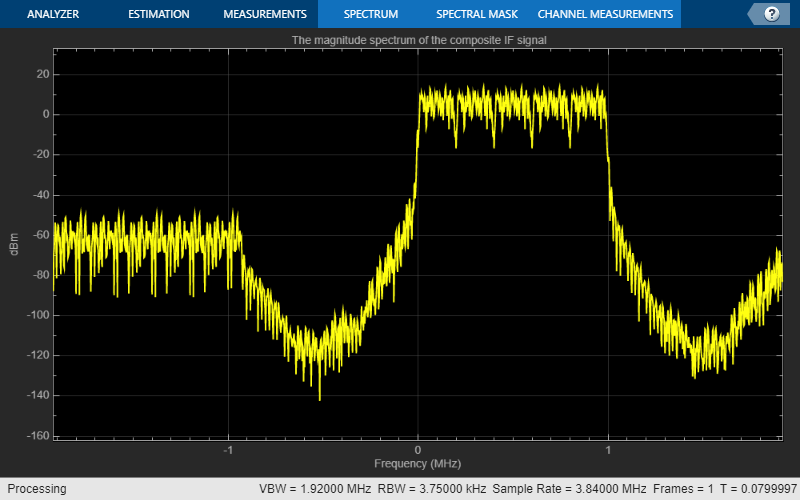

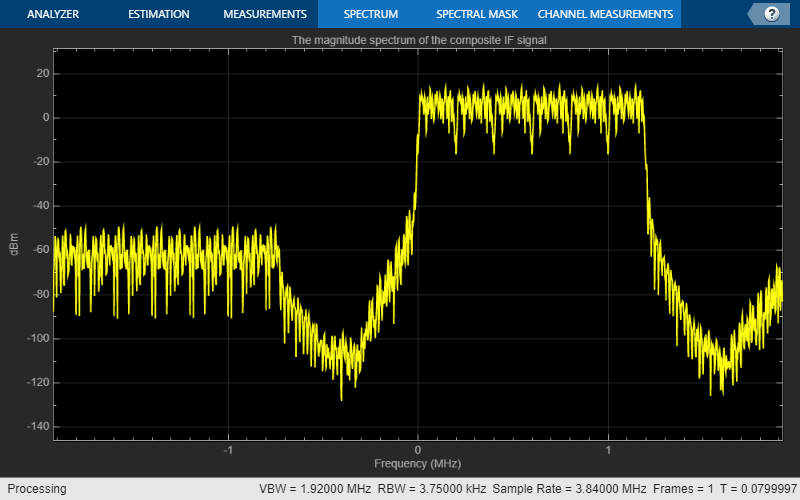

%Calculating the Intermediate frequency of each waveform and digitally upconverting
%the signal into this IF
NEW_Fs=Fs*2;
IF=IF_1+(2*IF_1*(i-1));
N=0:length(wave_filtered)-1;
DUC =exp(-1i*2*pi*N*IF*(1/NEW_Fs));
DUC_Signal= DUC'.*wave_filtered;
% Frequency multiplexing of the 6 signals
Trans_Signal=Trans_Signal+DUC_Signal;
% Visualizing the frequency domain of the transmitted signal 
  inputSpectrum = dsp.SpectrumAnalyzer('SampleRate',NEW_Fs,'Title',' The magnitude spectrum of the composite IF signal');
  inputSpectrum(Trans_Signal);
end

## **Receiving at the base station:**

At the base station, the received composite Intermediate Frequency (IF) signal undergoes a series of processes to reconstruct the uplink generated waveform at the transmitter side. These procedures include digital downconversion, followed by Finite Impulse Response (FIR) filtering using a low-pass filter.

finalWave=zeros(length(Trans_Signal)/2,6);
wave_DDC_signal=zeros(length(Trans_Signal),6);
wave_DDC_filter=zeros(length(Trans_Signal),6);

 for i=1:6
% Performing DDC on every signal to shift its center frequency to zero
IF=IF_1+(2*IF_1*(i-1));
N=1:length(Trans_Signal);
DDC =exp(1i*2*pi*N*IF*(1/NEW_Fs));
wave_DDC_signal(:,i) = DDC'.*Trans_Signal;
%filtering the signal in order to remove any noise lying outside the
%bandwidth of the signal using a window FIR low pass filter
wave_DDC_filter(:,i)=filter(Filter_optimal,1,wave_DDC_signal(:,i));
% Downsampling the signal by a factor of 2 
finalWave(:,i)=downsample(wave_DDC_filter(:,i),2);
 end

The 3 plots of one of the received NB-IoT waveforms (specifically of 4th order) 

First plot: after the digital down conversion process.

Second plot: after passing the signal through FIR low pass filter.

Thrid plot: after downsampling the signal by a factor of 2 to obtain the frequency of the uplink waveform generation.

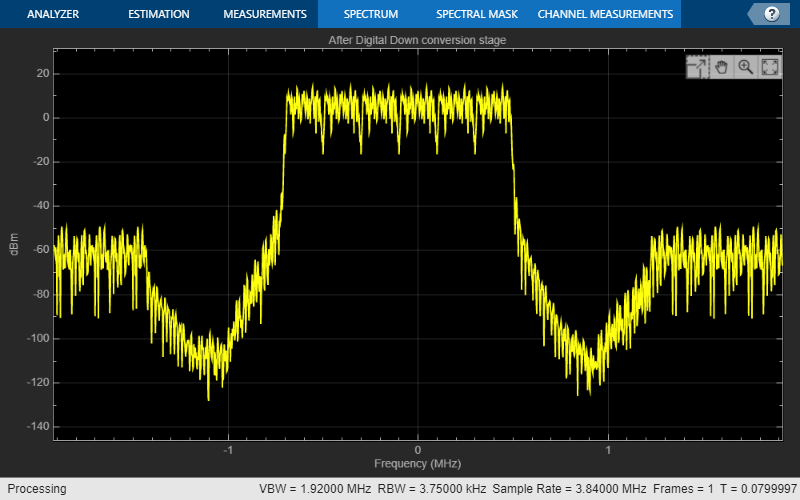

outputspectrum = dsp.SpectrumAnalyzer('SampleRate',NEW_Fs, 'Title','After DDC stage');
outputspectrum(wave_DDC_signal(:,4));

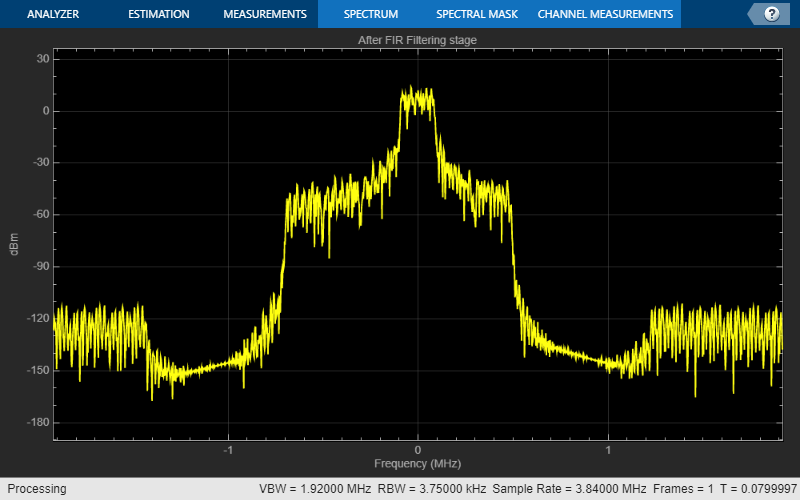


outputspectrum_2 = dsp.SpectrumAnalyzer('SampleRate',NEW_Fs,'Title','After FIR Filtering stage');
outputspectrum_2(wave_DDC_filter(:,4));

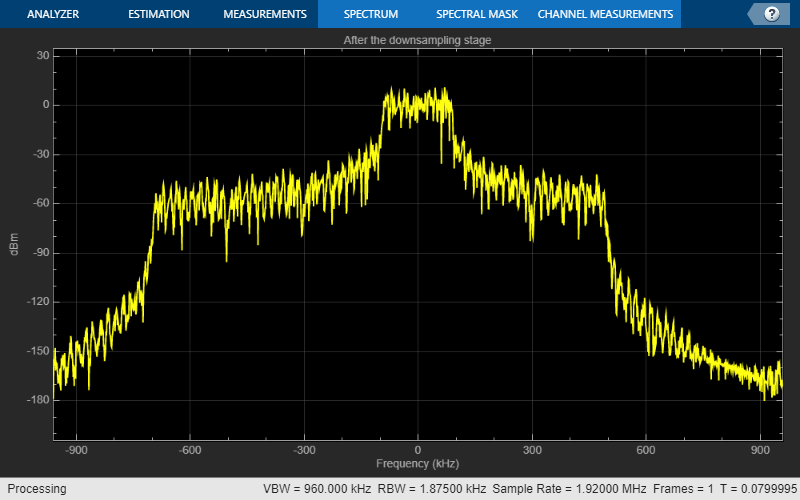

outputspectrum_3 = dsp.SpectrumAnalyzer('SampleRate',Fs,'Title','After the downsampling stage');
outputspectrum_3(finalWave(:,4));

## Block Diagrams

### Block Diagram of the 6 IoT devices transmitters:

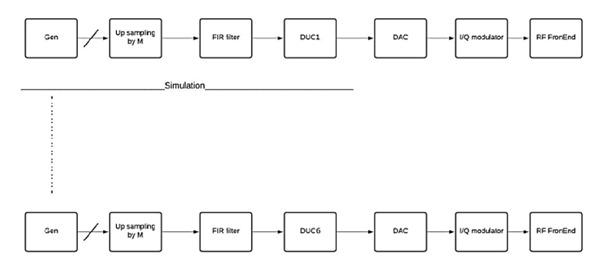

### Block Diagram of the base station receiver:

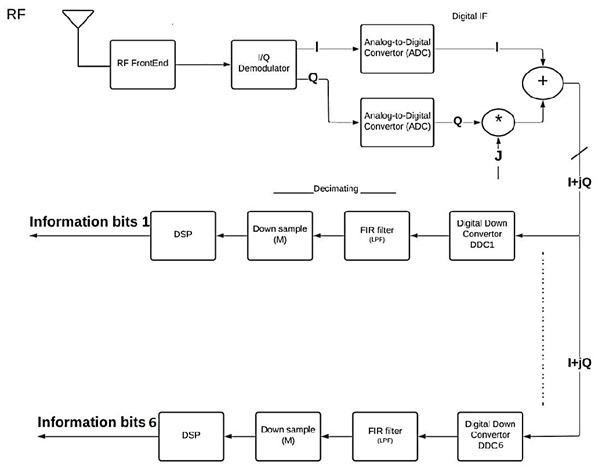

## Discussion of NB-IoT application:

NB-IoT technologies, with their simpler waveforms, offer significant advantages in power consumption and cost-effectiveness. With a narrower bandwidth of 200 kHz, their frontend and digitizer reduce complexity in conversion, buffering, and channel estimation, leading to significant power savings and cost reductions. This simplicity also facilitates a simpler manufacturing process, making the technology more accessible and economical. In addition, NB-IoT applications have far-reaching implications across public health, safety, and broader societal domains.

### **Smart Hospitals' Impact****:**

In the healthcare sector, the implementation of NB-IoT in smart medical beds has the potential to revolutionize patient care. Interactive Patient-Care Systems equipped with NB-IoT allow for enhanced communication and entertainment options, catering to patients with varying degrees of mobility. These systems also offer control over the environment, including informative resources about different medical conditions. The economic impact is noteworthy, as the technology can lead to cost-effective upgrades for other devices, benefiting less-developed regions with manual beds.

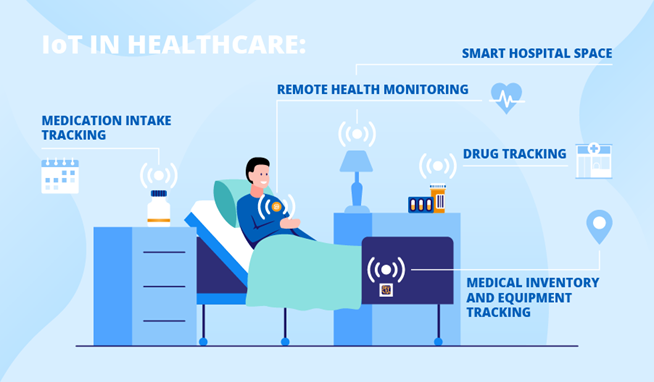

NB-IoT's application in environmental monitoring serves as a pivotal tool for safeguarding public health by assessing air and water quality. Through the deployment of NB-IoT sensors, an intricate web of pollutants, including particulate matter, nitrogen dioxide, and volatile organic compounds, can be continuously monitored in real-time. This comprehensive and dynamic data stream offers authorities insights into the quality of the environment, enabling timely interventions to mitigate potential health risks associated with pollution.

 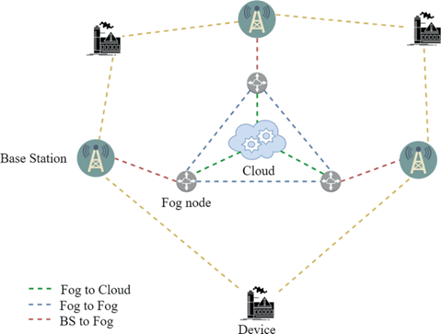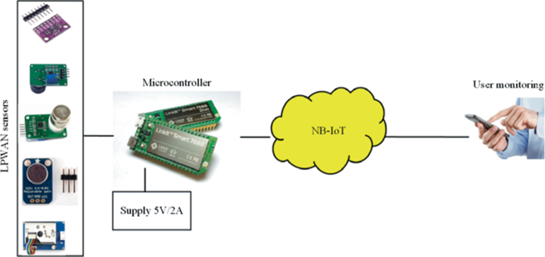

### **Safety****:**

In the realm of safety, NB-IoT emerges as a crucial technology by monitoring environmental conditions prone to disasters, such as floods or forest fires. The strategic placement of NB-IoT sensors in disaster-prone areas allows for the detection of critical changes, such as temperature increases or smoke formation. These sensors act as early warning systems, triggering immediate alerts. This proactive approach not only aids in early evacuation but also minimizes casualties and property damage.

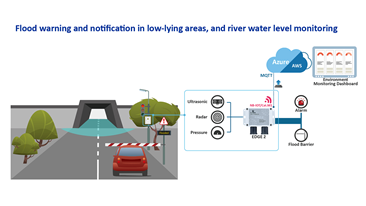

### **Social Impact****:** 

Beyond the technological aspects, NB-IoT’s impact extends to social dimensions, fostering awareness and citizen engagement. The accessibility of real-time environmental data through user-friendly interfaces and mobile apps empowers communities to actively engage in environmental conservation efforts. This engagement is not merely about increasing awareness; it can lead to collective efforts in reducing pollution, conserving resources, and advocating for environmentally friendly policies.

 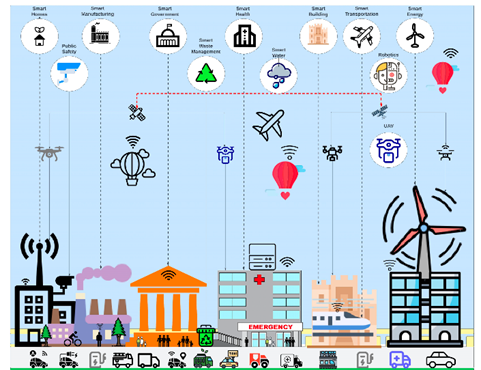

### **Environmental Factors****:**

NB-IoT proves instrumental in understanding and mitigating the impact of human activities on the environment beyond air quality. Sensors monitor diverse environmental factors, including industrial emissions, deforestation, and soil health. The resulting data informs policymakers about specific environmental challenges, enabling the formulation of targeted interventions for sustainable development.

 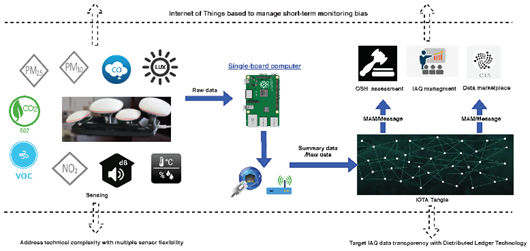

### **Economic Aspects****:**

An often-overlooked facet of NB-IoT’s influence is its economic impact, optimizing resource allocation and reducing long-term environmental cleanup costs. Timely interventions based on environmental data, such as predicting and preventing industrial accidents or mitigating the impact of natural disasters, can result in substantial economic savings.

 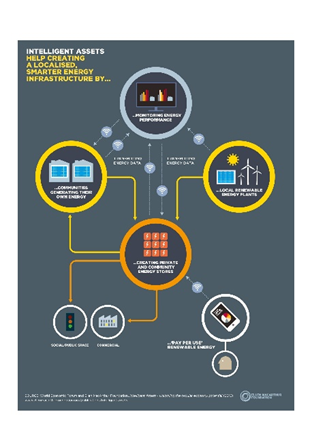

### **Relevant References:** 

Moursi, A. S., El-Fishawy, N., Djahel, S., & Shouman, M. A. (2021, July 29). *An IOT enabled system for enhanced air quality monitoring and prediction on the edge - complex & intelligent systems*. SpringerLink. [https://link.springer.com/article/10.1007/s40747-021-00476-w](https://link.springer.com/article/10.1007/s40747-021-00476-w)  

*Mitigating extreme climates through IOT remote monitoring*. Mitigating extreme climates through IoT remote monitoring. (2023, May 18). [https://iebmedia.com/technology/iiot/mitigating-extreme-climates-through-iot-remote-monitoring/](https://iebmedia.com/technology/iiot/mitigating-extreme-climates-through-iot-remote-monitoring/)

 Hassebo, A., & Tealab, M. (2023, August 31). *Global models of smart cities and potential IOT applications: A Review*. MDPI. [https://www.mdpi.com/2624-831X/4/3/17](https://www.mdpi.com/2624-831X/4/3/17)

Sun, S., Zheng, X., Villalba-Díez, J., & Ordieres-Meré, J. (2019, September 25). *Indoor air-quality data-monitoring system: Long-term monitoring benefits*. MDPI. [https://www.mdpi.com/1424-8220/19/19/4157](https://www.mdpi.com/1424-8220/19/19/4157)

Michell, N. (2016, March 3). *IOT is crucial for Circular Economy Development, reveals New report*. Cities Today. [https://cities-today.com/iot-technologies-crucial-to-moving-towards-a-circular-economy-according-to-new-report/](https://cities-today.com/iot-technologies-crucial-to-moving-towards-a-circular-economy-according-to-new-report/)

Cengiz, K., Ozyurt, B., Singh, K. K., Sharma, R., Topac, T., & Chatterjee, J. M. (1970, January 1). *The role of IOT and Narrow Band (NB)-IOT for several use cases*. SpringerLink. [https://link.springer.com/chapter/10.1007/978-3-030-66222-6_11](https://link.springer.com/chapter/10.1007/978-3-030-66222-6_11)